% Read the excel files for supply and demand
% When trying to see graphs on your own:
% CHANGE THE PINK PATHS TO SUPPLY AND DEMAND SPREADSHEETS

filename = 'C:\Users\jansl\OneDrive - TU Eindhoven\Desktop\4CBLA30\Team28_supply.csv';
Supply = readtable(filename);


filename = 'C:\Users\jansl\OneDrive - TU Eindhoven\Desktop\4CBLA30\Team28_demand.csv';
Demand = readtable(filename);

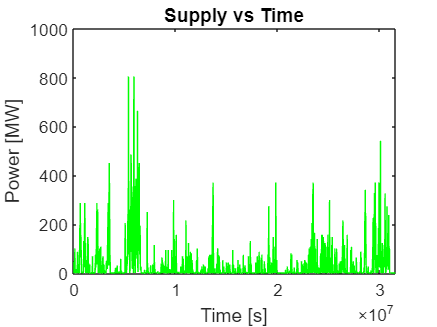


% Plot the supply and demand graphs

figure; % Supply
plot(Supply{:,1}, Supply{:,2}, 'g')
xlabel('Time [s]')
ylabel('Power [MW]')
title('Supply vs Time')

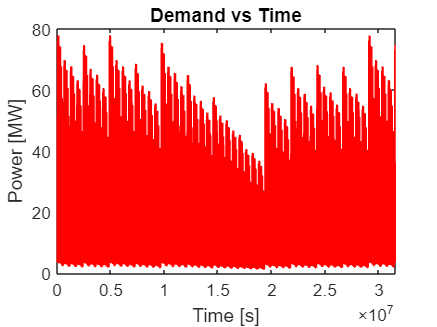


figure; % Demand
plot(Demand{:,1}, Demand{:,2}, 'r')
xlabel('Time [s]')
ylabel('Power [MW]')
title('Demand vs Time')

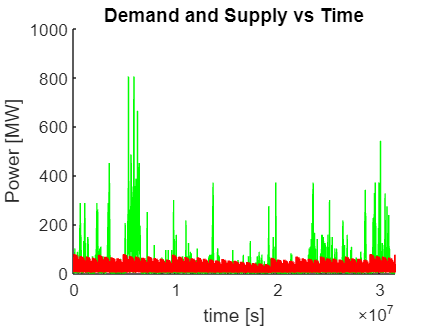


figure; % Supply and demand
hold on;
plot(Supply{:,1}, Supply{:,2}, 'g')
plot(Demand{:,1}, Demand{:,2}, 'r')
xlabel('time [s]')
ylabel('Power [MW]')
title('Demand and Supply vs Time')
hold off;

xlim([0 31535100])
ylim([0 1000])

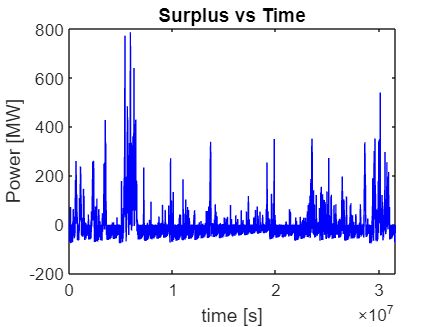


% Energy surplus
Surplus = Supply{:,2} - Demand{:,2};
Time = Demand{:,1}; % Extracting time
figure
plot(Time, Surplus,'b')
xlabel('time [s]')
ylabel('Power [MW]')
title('Surplus vs Time')


% Total demand


% Total surplus of energy in tera jules
x = Time;
y = Surplus;
Total_Surplus = (trapz(x,y)) / 10^6; % To make in TJ
max_demand_storage = min(Surplus)

max_demand_storage = -77.8236

max_supply_storage = max(Surplus)

max_supply_storage = 785.0053

fprintf('The total energy surplus is %6.3f TJ.',Total_Surplus);

The total energy surplus is 189.219 TJ.

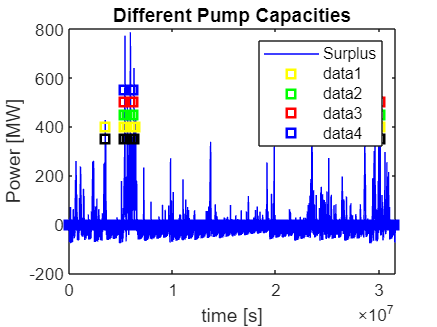


% Surplus over a given value
Surplus_over350 = Surplus > 350;
Surplus_over350 = 350 * Surplus_over350;

Surplus_over400 = Surplus > 400;
Surplus_over400 = 400 * Surplus_over400;

Surplus_over450 = Surplus > 450;
Surplus_over450 = 450 * Surplus_over450;

Surplus_over500 = Surplus > 500;
Surplus_over500 = 500 * Surplus_over500;

Surplus_over550 = Surplus > 550;
Surplus_over550 = 550 * Surplus_over550;

plot(Time, Surplus,'b')
hold on
plot(Time, Surplus_over350, 'k s', Linewidth=2)
legend("Surplus")
plot(Time, Surplus_over400, 'y s', Linewidth=2)
plot(Time, Surplus_over450, 'g s', Linewidth=2)
plot(Time, Surplus_over500, 'r s', Linewidth=2)
plot(Time, Surplus_over550, 'b s', Linewidth=2)

xlabel('time [s]')
ylabel('Power [MW]')
title('Different Pump Capacities')
hold off

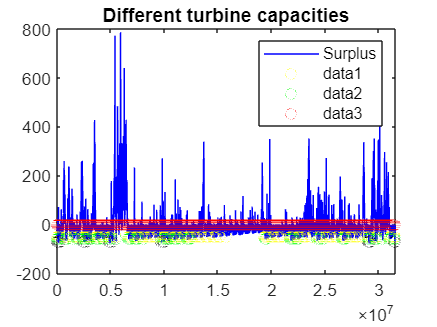

% Optimisiation of turbine size

Surplus_over50 = Surplus < -50;
Surplus_over50 = -50 * Surplus_over50;

Surplus_over60 = Surplus < -60;
Surplus_over60 = -60 * Surplus_over60;

Surplus_over70 = Surplus < -70;
Surplus_over70 = -70 * Surplus_over70;

Surplus_over80 = Surplus < -80;
Surplus_over80 = -80 * Surplus_over80;

plot(Time, Surplus,'b')
hold on
plot(Time, Surplus_over70, 'k o', Linewidth=0.1)
legend("Surplus")
plot(Time, Surplus_over50, 'y o', Linewidth=0.1)
plot(Time, Surplus_over60, 'g o', Linewidth=0.1)
plot(Time, Surplus_over80, 'r o', Linewidth=0.1)
legend
title("Different turbine capacities")
hold off